# Continuation of quasiperiodic invariant tori

Two-dimensional quasiperiodic invariant tori are characterized by a parallel flow with irrational rotation number. In terms of a suitably defined torus function, the dynamics on the torus may be described by an invariant circle that is mapped to itself by the flow, such that the flow is equivalent to a rigid rotation on the circle.

We obtain an approximate description of a quasiperiodic invariant torus in terms of a Fourier representation of the invariant circle and a finite collection of trajectory segments based at points on the invariant circle. The rigid rotation imposes an all-to-all coupled system of boundary conditions on the collection of trajectory segments.

Here we consider Van der Pol oscillator subject to harmonic excitation as follows


$$\ddot{x}-c(1-x^2)\dot{x}+x=a\cos\Omega t$$


and we are interested in the quasiperiodic response of such a system. We use this example to demonstrate the functionality of the tor toolbox

- **ode_isol2tor**: continuation of tori from a gusss initial solution

- **ode_tor2tor**: continuation of tori from a stored torus solution

- **ode_BP2tor**: continuation of tori along the secondary branch of tori of a branch point 

- *post-processing*: tor_read_solution, plot_torus

## ode_isol2tor

**Construct the guess of initial solution**

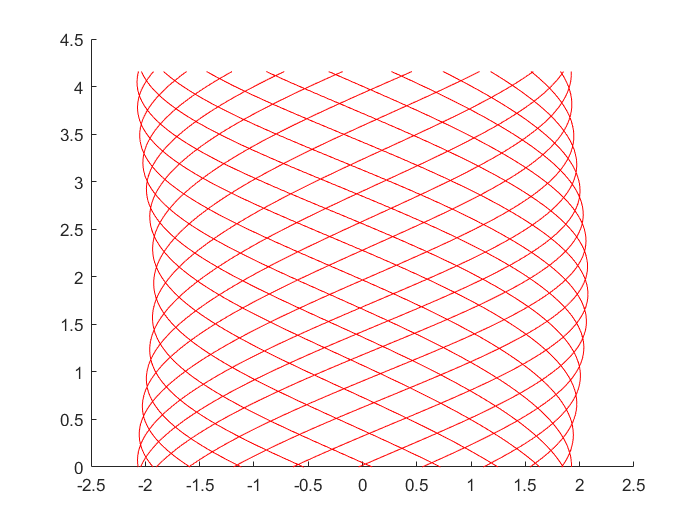

% pnames = [  om     c     a ]
p0       = [ 1.5111; 0.11; 0.1 ];

T_po = 2*pi; % Approximate period
N    = 10;   % 2N+1 = Number of orbit segments
tout = linspace(0, T_po, 2*N+2);

T_ret = 2*pi/p0(1); % return time = 2*pi/om
tt    = linspace(0,1,10*(2*N+1))';
t1    = T_ret*tt;
x0    = zeros(numel(tt),2,2*N+1);

figure; hold on
for i=1:2*N+1 % For each point on orbit, flow for return time and reconstitute 3D trajectory
  x1       = [2*cos(tout(i)) 2*sin(tout(i))];
  [~, x1] = ode45(@(t,x) vdp(t,x,p0), 10*t1, x1); % Transient simulation
  [~, x1] = ode45(@(t,x) vdp(t,x,p0), t1, x1(end,:));
  x0(:,:,i) = x1;
  plot3(x1(:,1),t1,x1(:,2),'r-');
end


varrho = T_ret/T_po;

**Construct continuation problem**

prob = coco_prob();
prob = coco_set(prob, 'tor', 'autonomous', false);
prob = coco_set(prob, 'coll', 'NTST', 40);
prob = coco_set(prob, 'cont', 'NAdapt', 0, 'h_max', 2, 'PtMX', 60);
torargs = {@vdp @vdp_DFDX @vdp_DFDP @vdp_DFDT t1 x0 {'Om2','c','a','om1','om2','varrho'} [p0' -2*pi/T_po p0(1) -varrho]};
% we choose negative om1 above because the rotation direction is opposite.
% In other words, the value of om1 can be both positive and negative
prob = ode_isol2tor(prob, '', torargs{:});

fprintf('\n Run=''%s'': Continue family of quasiperiodic invariant tori.\n', ...
  'torus');


 Run='torus': Continue family of quasiperiodic invariant tori.



coco(prob, 'vdP_torus', [], 1, {'a','Om2','om2','om1', 'varrho','c'}, {[0.1 2] [1 2]});


    STEP   DAMPING               NORMS              COMPUTATION TIMES
  IT SIT     GAMMA     ||d||     ||f||     ||U||   F(x)  DF(x)  SOLVE
   0                          1.57e-01  1.32e+02    0.0    0.0    0.0
   1   1  1.00e+00  6.01e+00  5.21e-03  1.32e+02    0.1    0.1    0.0
   2   1  1.00e+00  4.65e-01  2.77e-05  1.32e+02    0.1    0.1    0.1
   3   1  1.00e+00  1.56e-03  3.89e-10  1.32e+02    0.1    0.2    0.1
   4   1  1.00e+00  4.46e-08  4.38e-14  1.32e+02    0.1    0.3    0.2

 STEP      TIME        ||U||  LABEL  TYPE             a          Om2          om2          om1       varrho            c
    0  00:00:02   1.3150e+02      1  EP      1.0000e-01   1.5100e+00   1.5100e+00  -9.9925e-01  -6.6177e-01   1.1000e-01
   10  00:00:07   1.3129e+02      2          2.7767e-01   1.5101e+00   1.5101e+00  -9.9932e-01  -6.6177e-01   1.1000e-01
   20  00:00:13   1.3057e+02      3          5.4885e-01   1.5104e+00   1.5104e+00  -9.9954e-01  -6.6177e-01   1.1000e-01
   30  00:00:18   1.2945

## ode_tor2tor: restart from previous solution

bd  = coco_bd_read('vdP_torus');
lab = coco_bd_labs(bd, 'EP');
lab = max(lab);
prob = coco_prob();
prob = coco_set(prob, 'cont', 'NAdapt', 5, 'h_max', 2, 'PtMX', 60);
prob = ode_tor2tor(prob, '', 'vdP_torus', lab);

fprintf('\n Run=''%s'': Continue family of quasiperiodic invariant tori.\n', ...
  'vdP_torus_varrho');


 Run='vdP_torus_varrho': Continue family of quasiperiodic invariant tori.



coco(prob, 'vdP_torus_varrho', [], 1, {'a','Om2','om2','varrho','om1','c'}, {[0.1 2] [1 2]});


    STEP   DAMPING               NORMS              COMPUTATION TIMES
  IT SIT     GAMMA     ||d||     ||f||     ||U||   F(x)  DF(x)  SOLVE
   0                          1.00e-13  1.25e+02    0.0    0.0    0.0

 STEP      TIME        ||U||  LABEL  TYPE             a          Om2          om2       varrho          om1            c
    0  00:00:00   1.2475e+02      1  EP      1.4183e+00   1.5120e+00   1.5120e+00  -6.6177e-01  -1.0006e+00   1.1000e-01
   10  00:00:06   1.2472e+02      2          1.2196e+00   1.4831e+00   1.4831e+00  -6.7463e-01  -1.0006e+00   1.1000e-01
   20  00:00:12   1.2241e+02      3          8.7627e-01   1.4183e+00   1.4183e+00  -7.0549e-01  -1.0006e+00   1.1000e-01
   25  00:00:17   1.2132e+02      4  BP      7.1233e-01   1.3785e+00   1.3785e+00  -7.2582e-01  -1.0006e+00   1.1000e-01
   26  00:00:21   1.1988e+02      5  BP      6.8307e-01   1.3707e+00   1.3707e+00  -7.2999e-01  -1.0006e+00   1.1000e-01
   30  00:00:23   1.2025e+02      6          5.6443e-01   1.33

## ode_BP2tor: switch to secondary branch

bd  = coco_bd_read('vdP_torus_varrho');
lab = coco_bd_labs(bd, 'BP');
lab = lab(1);
prob = coco_prob();
prob = coco_set(prob, 'cont', 'NAdapt', 0, 'h_max', 2, 'PtMX', 60);
prob = ode_BP2tor(prob, '', 'vdP_torus_varrho', lab);

fprintf('\n Run=''%s'': Continue family of quasiperiodic invariant tori.\n', ...
  'vdP_torus_varrho_BP');


 Run='vdP_torus_varrho_BP': Continue family of quasiperiodic invariant tori.



coco(prob, 'vdP_torus_varrho_BP', [], 1, {'a','Om2','om2','varrho','om1','c'}, {[0.1 2] [1 2]});


 STEP      TIME        ||U||  LABEL  TYPE             a          Om2          om2       varrho          om1            c
    0  00:00:01   1.1988e+02      1  EP      6.8307e-01   1.3707e+00   1.3707e+00  -7.2999e-01  -1.0006e+00   1.1000e-01
    1  00:00:03   1.1988e+02      2  BP      6.8307e-01   1.3707e+00   1.3707e+00  -7.2999e-01  -1.0006e+00   1.1000e-01
    2  00:00:04   1.1988e+02      3  FP      6.8307e-01   1.3707e+00   1.3707e+00  -7.2999e-01  -1.0006e+00   1.1000e-01
   10  00:00:08   1.1940e+02      4          6.9443e-01   1.3705e+00   1.3705e+00  -7.3009e-01  -1.0006e+00   1.1000e-01
   20  00:00:12   1.1732e+02      5          7.4812e-01   1.3699e+00   1.3699e+00  -7.3041e-01  -1.0006e+00   1.1000e-01
   30  00:00:17   1.1698e+02      6          7.5807e-01   1.3698e+00   1.3698e+00  -7.3045e-01  -1.0006e+00   1.1000e-01
   40  00:00:22   1.1672e+02      7          7.6636e-01   1.3697e+00   1.3697e+00  -7.3048e-01  -1.0006e+00   1.1000e-01
   44  00:00:24   1.1664e+02   

## Visualization of results

Plot of continuation path

figure; hold 

Current plot held


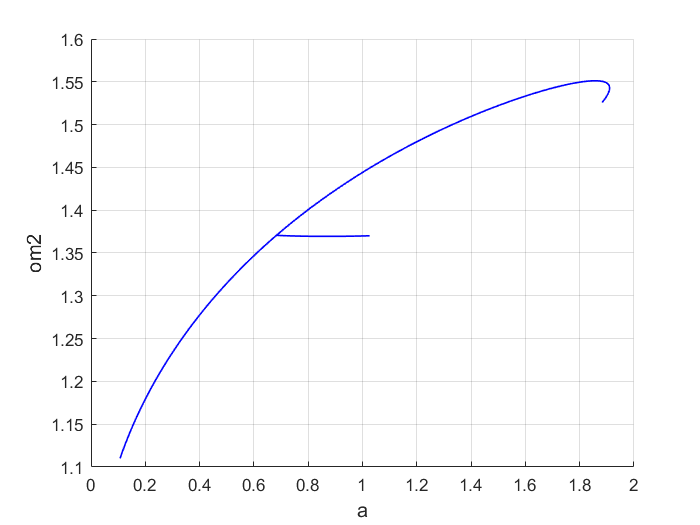

coco_plot_bd('vdP_torus_varrho', 'a', 'om2');hold on
coco_plot_bd('vdP_torus_varrho_BP', 'a', 'om2'); % secondary branch
grid on

Here we show how to use tor_read_solution

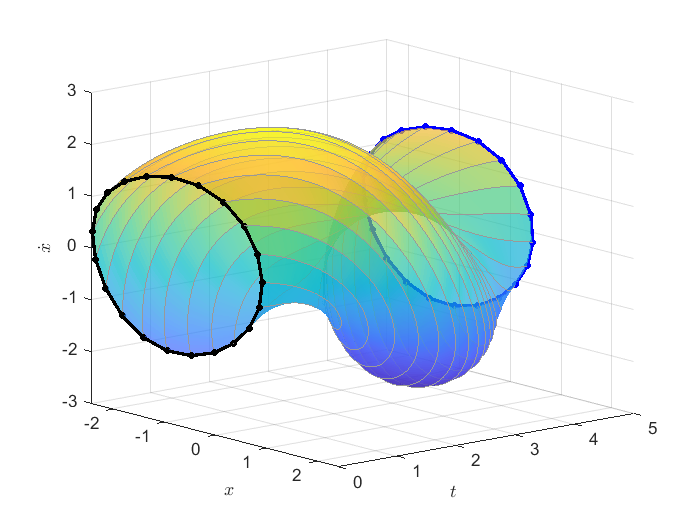

[sol, data] = tor_read_solution('', 'vdP_torus_varrho_BP', 1);
tube = sol.xbp;
tube = permute(tube, [1,3,2]);
tbp  = repmat(sol.tbp, [1,data.nsegs+1]);
figure; hold on
surf(tube(:,:,1), tbp, tube(:,:,2), 'FaceAlpha', 0.7, ...
    'MeshStyle', 'column', 'LineStyle', '-', 'EdgeColor', 0.6*[1 1 1], ...
    'LineWidth', 0.5);
plot3(tube(1,:,1), zeros(data.nsegs+1,1), tube(1,:,2), 'LineStyle', '-', 'LineWidth', 2, ...
    'Color', 'black', 'Marker', '.', 'MarkerSize', 12);
plot3(tube(end,:,1), tbp(end)*ones(data.nsegs+1,1), tube(end,:,2), 'LineStyle', '-', 'LineWidth', 2, ...
    'Color', 'blue', 'Marker', '.', 'MarkerSize', 12);
xlabel('$x$','Interpreter',"latex");
ylabel('$t$','Interpreter',"latex");
zlabel('$\dot{x}$','Interpreter',"latex")
view([50 15]); grid on

Or you may simply call plot_torus for plotting

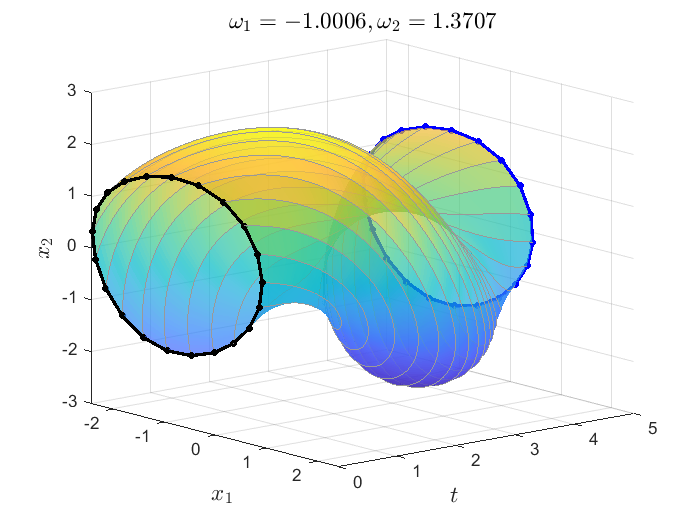

plot_torus('','vdP_torus_varrho_BP', 1, [1 2]);

## Remarks

- The toolbox also supports the computation of torus in autonomous system (two phase conditions are needed). Please see demo langford for more details.

- The continuation in this demo starts from an initial guess. It is not trivial to construct good initial guess. On the other hand, TR bifurcation points could be detected in the cotinuation of periodic orbits. TR point indicates the apperance of quasi-periodic resposne. ode_TR2tor is developed as well to switch continuation from periodic orbits to tori. Please see demoTR in current folder for more details.